%Generate Training Data
%Generate training data at SNRs [2,10,23] and BOs [1,7,30] 

M = 16;
nb = 10014; %number of integers 

EbNo = 10; 
packets = 100; 
window = 4; 

rng(0)

agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400);  
PA = comm.MemorylessNonlinearity('Method', 'Saleh model');
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4); %create awgn channel object
txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion

for SNR = [2,10,23]
    awgnChan.EbNo = SNR;  %set channel snr
    for BO = [1,7,30]
        if BO == 1
            PA.InputScaling = 9;
        elseif BO == 7
            PA.InputScaling = 3.5; 
        else 
            PA. InputScaling = -20;
        end 
    
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x'); 
        txfilterData = txfilter(symbols); 
        txfilterData = PA(txfilterData);%hpa
        txData = txfilterData.*y; %upconvert

        txData = awgnChan(txData); %noise
        
        rxData = txData.*conj(y); %down convert
        rxData = agc(rxData); 
        rx = rxfilter(rxData); %SRRC filter
        
        d = finddelay(symbols, rx); %need to remove delay before windowing
        rx = rx((d+1):end); %get rid of filter delay 
        symbols = symbols(1:(end-d));
        
        train_data = makeInputMat(rx,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
        
        x_train = zeros(size(train_data,1),size(train_data,2)*packets);
        y_train = zeros(size(target,1),size(target,2)*packets);
        
        %validation data
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x');
        txfilterData = txfilter(symbols); %srrc
        txfilterData = PA(txfilterData);%hpa
        txData = txfilterData.*y; %upconvert
        
        txData = awgnChan(txData); %noise

        rxData = txData.*conj(y); %down convert
        rxData = agc(rxData); 
        rx = rxfilter(rxData); %SRRC filter
        
        d = finddelay(symbols, rx); %need to remove delay before windowing
        rx = rx((d+1):end); %get rid of filter delay 
        symbols = symbols(1:(end-d));
        
        val_data = makeInputMat(rx,window);
        val_data = val_data(:,1:end-window);
        symbols = symbols(1+window:end);
        val_target = round([real(symbols) imag(symbols)],5)';
      
        %train data
        for iter = 1:packets
            x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
            y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
            if iter ~= packets
                msg = randi([0 sum(M)-1], nb, 1);
                symbols = dvbsapskmod(msg, M, 's2x');
                txfilterData = txfilter(symbols); %srrc
                txfilterData = PA(txfilterData);
                txData = txfilterData.*y; %upconvert
                
                txData = awgnChan(txData); %noise

                rxData = txData.*conj(y); %down convert
                rxData = agc(rxData); 
                rx = rxfilter(rxData); %SRRC filter
        
                d = finddelay(symbols, rx); %need to remove delay before windowing
                rx = rx((d+1):end); %get rid of filter delay 
                symbols = symbols(1:(end-d)); %align with rx
        
                train_data = makeInputMat(rx,window);
                train_data = train_data(:,1:end-window);
                symbols = symbols(1+window:end);
                target = round([real(symbols) imag(symbols)],5)';
            end 
        end 
        
        x_train = x_train'; 
        y_train = y_train';
        
        val_data = val_data'; 
        val_target = val_target'; 

        filename = sprintf('DVBSAPSK_data_SNR_%d_BO_%d', [SNR, BO]);
        save(filename, 'x_train', 'y_train', 'val_data', 'val_target'); 
    end 
end 

%Generate testing data
%The BO is held constant and the SNR will vary between -2:23 dB. 10 packets
%of each are generated 
%filename convention: DVBSAPSK_pred_bo_%d_snr_%d_%d.mat 
%bo_%d: represents current backoff
%snr_%d: snr of awgn channel 
%_%d: packet number (1-10)

rng(0); 
M=16;
window = 4;
nb = 100014;

cd('Test Data')

%communication things 
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4); %create awgn channel object
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up/down conversion
PA = comm.MemorylessNonlinearity('Method', 'Saleh model'); %high power amplifier 
agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400); %gain control

txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc

for BO = [1,7,30]
    %adjust back off
    if BO == 1
        PA.InputScaling = 9;
    elseif BO == 7
        PA.InputScaling = 3.5; 
    else 
        PA. InputScaling = -20; 
    end 
    for EbNo = -2:23
        awgnChan.EbNo = EbNo; %adjust snr
        for i = 1:10
            msg = randi([0 sum(M)-1], nb, 1);
            symbols = dvbsapskmod(msg, M, 's2x'); 
            txfilterData = txfilter(symbols); 
            txfilterData = PA(txfilterData);
            txData = txfilterData.*y; %upconvert

            txData = awgnChan(txData); 
           
            rxData = txData.*conj(y); %down convert
            rxData = agc(rxData); %gain control 
            rx = rxfilter(rxData); %SRRC filter 
            
            d = finddelay(symbols, rx); %need to remove delay before windowing
            rx = rx((d+1):end); %get rid of filter delay 
            symbols = symbols(1:(end-d));
            
            train_data = makeInputMat(rx,window);
            train_data = train_data(:,1:end-window);
            symbols = symbols(1+window:end);
            target = round([real(symbols) imag(symbols)],5)';
            
            train_data = train_data'; 
            
            filename_test = sprintf('DVBSAPSK_pred_bo_%d_snr_%d_%d', [BO,EbNo,i]); 
            save(filename_test, 'train_data', 'target'); 
        end 
    end 
end


%Evaluate models 
M = 16;
train_snrs = [2,10,23]; %for iterating through folders 
path_test = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\NN Implementation\HPA AWGN\Test Data'; %path for original data
path_NN = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\NN Implementation\HPA AWGN\NN Output'; %path for NN Output

ber_total = zeros(3,26); 
ber_current = zeros(1,10); 
j = 1; %clmns
k = 1; %rows 

tic
for BO = [1]
    for train_snr = train_snrs
        foldername = sprintf('BO_%d_trainSNR_%d', [BO, train_snr]); %folder for accessing NN output
        for EbNo = -2:23
            for i = 1:10

                cd(path_NN)
                cd(foldername)

                %load NN output
                f_og = sprintf('DVBSAPSK_out_bo_%d_snr_%d_%d', [BO, EbNo, i]); 
                load(f_og)

                %load original train data
                cd(path_test)
                f = sprintf('DVBSAPSK_pred_bo_%d_snr_%d_%d', [BO, EbNo, i]); 
                load(f)
                
                pred = complex(pred(:,1), pred(:, 2));
                target = target';
                target_cp= complex(target(:,1), target(:, 2));
                
                %BER
                demodData_NN = dvbsapskdemod(pred, M, 's2x'); 
                demodData_ideal = dvbsapskdemod(target_cp, M, 's2x');
                
                demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type
                
                %calculate BER
                data_bit = int2bit(demodData_ideal, 4); %convert to bit
                output_bit = int2bit(demodData_NN, 4);%convert to bit
                
                d = finddelay(data_bit,output_bit); 
                errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
                err = errorRate(data_bit, output_bit); %get bit error
                ber_current(i)= err(1)*100;
                
            end 
            %average ber for current snr
            ber_total(j,k) = mean(ber_current); 
            k = k+1; %next channel snr
        end 
        k=1;
        j = j +1; %next train_snr
    end 
    j =1; %next back off
end 
toc

Elapsed time is 326.401508 seconds.


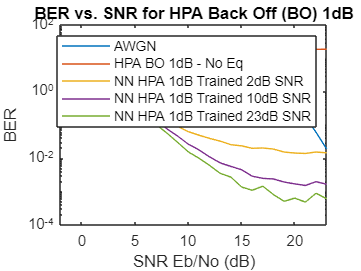

%plot results

path_ber ='C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\LNA and HPA\BER Plots';
cd(path_ber); 

path_awgn = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\AWGN Model\BER Plot';

ber_og=readmatrix('ber_lna_hpa.xls', 'Sheet', 'backOff1', 'Range','B2:AA2'); 
cd(path_awgn)

ber_awgn = readmatrix('ber.xls'); 

snr = -2:23; 

semilogy(snr, ber_awgn.*100, snr, ber_og.*100, snr, ber_total(1,:), snr, ber_total(2,:), snr, ber_total(3,:));
grid on
title('BER vs. SNR for HPA Back Off (BO) 1dB');
xlabel('SNR Eb/No (dB)');
ylabel('BER');
legend('AWGN', 'HPA BO 1dB - No Eq', 'NN HPA 1dB Trained 2dB SNR', 'NN HPA 1dB Trained 10dB SNR', 'NN HPA 1dB Trained 23dB SNR' ); 

BO = 1

BO = 1

EbNo = 5

EbNo = 5

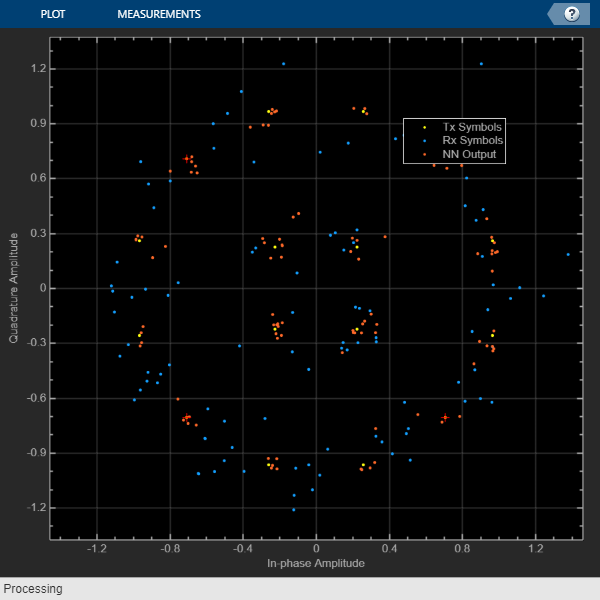

i = 1;

agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400);  
PA = comm.MemorylessNonlinearity('Method', 'Saleh model');
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', EbNo); %create awgn channel object
txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion

msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 
txfilterData = txfilter(symbols); 
txfilterData = PA(txfilterData);
txData = txfilterData.*y; %upconvert

txData = awgnChan(txData); 

rxData = txData.*conj(y); %down convert
rxData = agc(rxData); %gain control 
rx = rxfilter(rxData); %SRRC filter 

cd(path_NN)
cd(foldername)

%load NN output
f_og = sprintf('DVBSAPSK_out_bo_%d_snr_%d_%d', [BO, EbNo, i]); 
load(f_og)

%load original train data
cd(path_test)
f = sprintf('DVBSAPSK_pred_bo_%d_snr_%d_%d', [BO, EbNo, i]); 
load(f)

pred = complex(pred(:,1), pred(:, 2));
target = target';
target_cp= complex(target(:,1), target(:, 2));

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100,'ChannelNames', {'Tx Symbols', 'Rx Symbols', 'NN Output'});

constDiagram([target_cp(1:1000), rx(1:1000), pred(1:1000)]); 